# HW5

## Wei Ye

### Date: Jun 25, 2022

#### Question1

A=[[1:10]',[1 1 0 0 0 1 1 1 0 1]',[100 95 125 140 110 85 110 100 125 105]',[4 2 4 7 4 2 4 4 6 4]']

A =      1     1   100     4
     2     1    95     2
     3     0   125     4
     4     0   140     7
     5     0   110     4
     6     1    85     2
     7     1   110     4
     8     1   100     4
     9     0   125     6
    10     1   105     4


 a. Using for-loops to create two vectors, one containing the salaries of only maile(sal_m), the other for the salaries of only females(sal_f)

sal_m=[];
sal_f=[];
for i =1:size(A,1)
    if A(i,2)==0
        sal_m=[sal_m;A(i,3)]
    end
end

sal_m = 125

sal_m =    125
   140


sal_m =    125
   140
   110


sal_m =    125
   140
   110
   125


for i =1:size(A,1)
    if A(i,2)==1
        sal_f=[sal_f;A(i,3)]
    end
end

sal_f = 100

sal_f =    100
    95


sal_f =    100
    95
    85


sal_f =    100
    95
    85
   110


sal_f =    100
    95
    85
   110
   100


sal_f =    100
    95
    85
   110
   100
   105


b. using for loops to creat 2 matrices that have in their first column as id of the individuals and in the second column as the corresponding salary. Do this for male(id_sal_m) and females(id_sal_f)

id_sal_m=[];
id_sal_f=[];
for i =1:size(A,1)
    if A(i,2)==0
        id_sal_m=[sal_m;A(i,3)]
    end
end

id_sal_m =    125
   140
   110
   125
   125


id_sal_m =    125
   140
   110
   125
   140


id_sal_m =    125
   140
   110
   125
   110


id_sal_m =    125
   140
   110
   125
   125



for j=1:size(A,1)
    if A(j,2)==1
        id_sal_f=[id_sal_f;A(j,[1,3])]
    end
end

id_sal_f =      1   100


id_sal_f =      1   100
     2    95


id_sal_f =      1   100
     2    95
     6    85


id_sal_f =      1   100
     2    95
     6    85
     7   110


id_sal_f =      1   100
     2    95
     6    85
     7   110
     8   100


id_sal_f =      1   100
     2    95
     6    85
     7   110
     8   100
    10   105


c. Separate the data into males and females and compute the descriptive statisticals for sal_m and sal_f. Estimate the mean, median,variance, standard deviation, max, min and number of obseravations. The matrix names should be desc_stat_male and desc_stat_female;

desc_stats_male=[mean(sal_m),median(sal_m),var(sal_m),std(sal_m),max(sal_m),min(sal_m),size(sal_m,1)]

desc_stats_male =   125.0000  125.0000  150.0000   12.2474  140.0000  110.0000    4.0000


desc_stats_female=[mean(sal_f),median(sal_f),var(sal_f),std(sal_f),max(sal_f),min(sal_f),size(sal_f,1)]

desc_stats_female =    99.1667  100.0000   74.1667    8.6120  110.0000   85.0000    6.0000


d. Estimate the correlation between the salaries and the years of education after high school. Name the correlation corr_sal_years. Also estimate the p-values of the correlations. Name it as p_corr_sal_years.

[corr_sal_years,p_corr_sal_years]=corrcoef(A(:,3),A(:,4))

corr_sal_years =     1.0000    0.8911
    0.8911    1.0000


p_corr_sal_years =     1.0000    0.0005
    0.0005    1.0000


e. Do the same as before, but this time for males and females independently. Create a matrix with two columns: first column the years and second column the salaries for male and females. Name the matrices sal_year_m and sal_year_f. After this, estimate the correlations and p-values. Name the correlation matrices as corr_sal_years_m and corr_sal_years_f; the p-values should be named as p_corr_sal_years_m and p_corr_sal_years_f.

sal_year_m=[];
sal_year_f=[];
for i =1:size(A,1)
    if A(i,2)==0
        sal_year_m=[sal_year_m;A(i,[4,3])]
    end
end

sal_year_m =      4   125


sal_year_m =      4   125
     7   140


sal_year_m =      4   125
     7   140
     4   110


sal_year_m =      4   125
     7   140
     4   110
     6   125



for j =1:size(A,1)
    if A(j,2)==1
        sal_year_f=[sal_year_f;A(j,[4,3])]
    end
end

sal_year_f =      4   100


sal_year_f =      4   100
     2    95


sal_year_f =      4   100
     2    95
     2    85


sal_year_f =      4   100
     2    95
     2    85
     4   110


sal_year_f =      4   100
     2    95
     2    85
     4   110
     4   100


sal_year_f =      4   100
     2    95
     2    85
     4   110
     4   100
     4   105


[corr_sal_years_m,p_corr_sal_years_m]=corrcoef(sal_year_m(:,1),sal_year_m(:,2))

corr_sal_years_m =     1.0000    0.8165
    0.8165    1.0000


p_corr_sal_years_m =     1.0000    0.1835
    0.1835    1.0000


[corr_sal_years_f,p_corr_sal_years_f]=corrcoef(sal_year_f(:,1),sal_year_f(:,2))

corr_sal_years_f =     1.0000    0.8245
    0.8245    1.0000


p_corr_sal_years_f =     1.0000    0.0435
    0.0435    1.0000


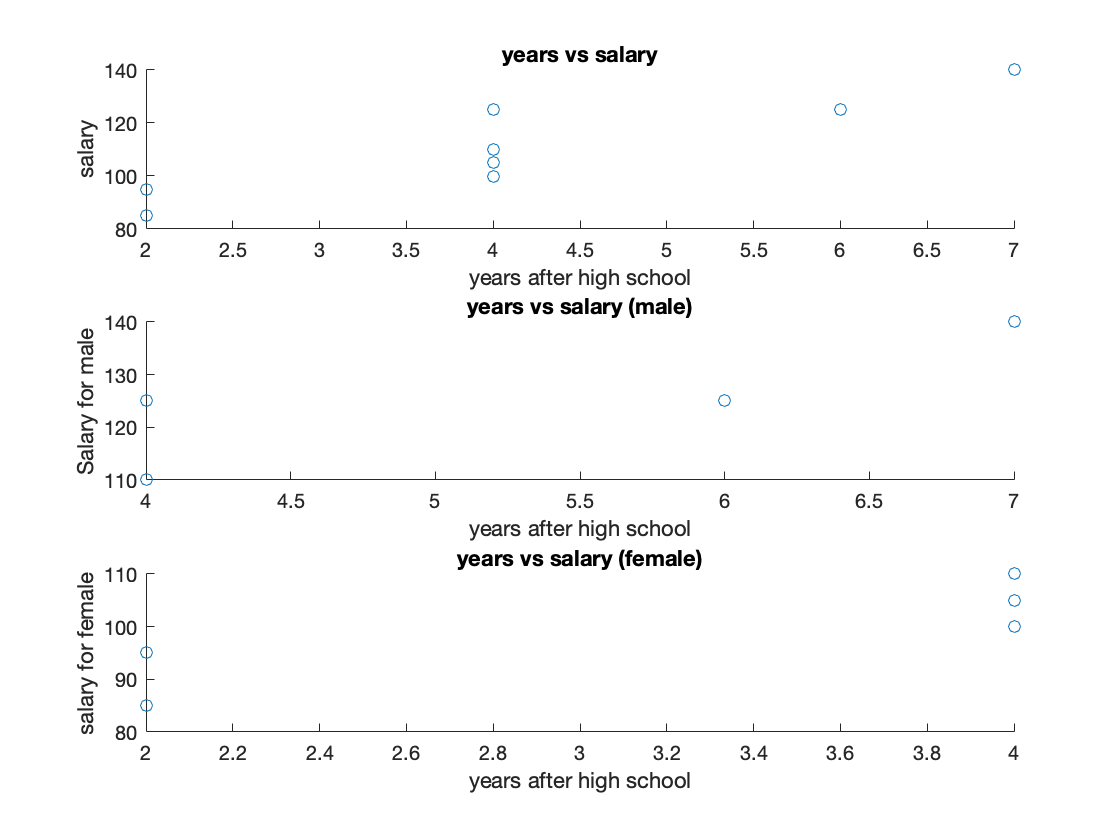

subplot(3,1,1)
scatter(A(:,4),A(:,3))
title("years vs salary")
xlabel("years after high school")
ylabel("salary")

subplot(3,1,2)
scatter(sal_year_m(:,1),sal_year_m(:,2))
title("years vs salary (male)")
xlabel("years after high school")
ylabel("Salary for male")

subplot(3,1,3)
scatter(sal_year_f(:,1),sal_year_f(:,2))
title("years vs salary (female)")
xlabel("years after high school")
ylabel("salary for female")

#### Question 2,(OLS question, same with last hw) see last homework file.